%eldc k0
Td = 0.8;%dac delay,0.8个时钟周期，Ts对时钟周期进行归一化

%1/s,1/s^2,1/s^3的脉冲响应
x1 = impulse(c2d(tf([1],[1 0]),1),10)

x1 =      0
     1
     1
     1
     1
     1
     1
     1
     1
     1


x2 = impulse(c2d(tf([1],[1 0 0]),1),10)

x2 =          0
    0.5000
    1.5000
    2.5000
    3.5000
    4.5000
    5.5000
    6.5000
    7.5000
    8.5000


x3 = impulse(c2d(tf([1],[1 0 0 0]),1),10)

x3 =          0
    0.1667
    1.1667
    3.1667
    6.1667
   10.1667
   15.1667
   21.1667
   28.1667
   36.1667



%理想的 Hs=k1/s+k2+s^2+k3/s^3;
imp_lct = x1*k1+x2*k2+x3*k3;

%1/s,1/s^2,1/s^3的具有Td延迟的脉冲响应
x1d = impulse(c2d(tf([1],[1 0],'InputDelay', Td),1),10)

x1d =          0
    0.2000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000


x2d = impulse(c2d(tf([1],[1 0 0],'InputDelay', Td),1),10)

x2d =          0
    0.0200
    0.7000
    1.7000
    2.7000
    3.7000
    4.7000
    5.7000
    6.7000
    7.7000


x3d = impulse(c2d(tf([1],[1 0 0 0],'InputDelay', Td),1),10)

x3d =          0
    0.0013
    0.2867
    1.4867
    3.6867
    6.8867
   11.0867
   16.2867
   22.4867
   29.6867



k3d = k3;
k2d = k2+k3*Td;
k1d = k1+k2*Td+k3*(Td^2/2);

imp_lct_delay = x1d*k1d+x2d*k2d+x3d*k3d;

delta = imp_lct - imp_lct_delay

delta =          0
    0.6181
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000



k0 = delta(2)

k0 = 0.6181


%k0等于n=1处的脉冲响应差值
y1 = k1+0.5*k2

y1 = 0.7924

y1d = (1-Td)*k1d+0.5*(1-Td)^2*k2d

y1d = 0.1815

k0d = y1-y1d

k0d = 0.6109


Feldc = tf([k0d],[1],'InputDelay', Td)

Feldc =
 
  exp(-0.8*s) * (0.6109)
 
Continuous-time transfer function.




xeldc = impulse(c2d(Feldc,1),10)

xeldc =          0
    0.6109
         0
         0
         0
         0
         0
         0
         0
         0


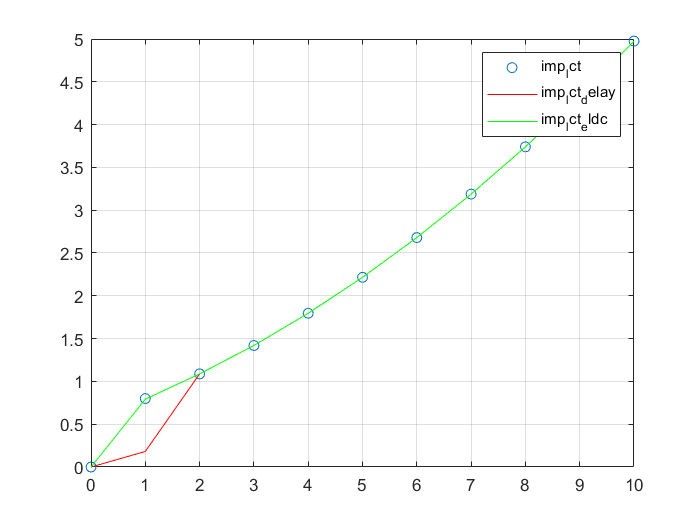


imp_lct_eldc = x1d*k1d+x2d*k2d+x3d*k3d + xeldc;

plot_imp_reponse_delay = 1;

if plot_imp_reponse_delay == 1
figure;
plot(0:10,imp_lct,'o');
hold on;
% plot(Ts:Ts+10,imp_lct_delay);
plot(0:10,imp_lct_delay,'r');
hold on;
plot(0:10,imp_lct_eldc,'g');
legend('imp_lct','imp_lct_delay','imp_lct_eldc');

grid on;
end